k1 = 1;
a02 = 1;
k2 = 0.5;
T2 = 0.95;
T = 0.5;

A = [0 1; 0 -a02/T2];
B = [0;1];
Bf = [0;1/k2];
C = [k1*k2/T2 0];

Ad = zeros([2 2]);
Bd = zeros([2 1]);
Bdf = zeros([2 1]); 
for i = 0:5
    Ad = Ad + A^i*T^i/factorial(i);
    Bd = Bd + A^i*T^(i+1)/factorial(i+1)*B;
    Bdf = Bdf + A^i*T^(i+1)/factorial(i+1)*Bf;
end

Gg = [0 1; -1 2];
Hg = [1 0];

Gf = [0 1; -1 2];
Hf = [1 0];

Gd = [0 1; 0 0];
Hd = [1 0];

syms mg3 mg4
syms lg1 lg2
Mg = [1/(k1*k2/T2) 0; mg3 mg4];
Lg = [lg1 lg2];

S = solve(Bd*Lg == Mg*Gg - Ad*Mg);

Mg = [1/(k1*k2/T2) 0; double(S.mg3) double(S.mg4)];
Lg = [double(S.lg1) double(S.lg2)];

M = sylvester(-Ad, Gd, Bd*Hd);
Koc = Hd*inv(M);

Mz = sylvester(-Ad',Gd,-C'*Hd);
L = (Hd*inv(Mz))';

Lf = [2 0];

Tmdl = 5;

x_initial = [1;-1];
x_hat_initial = [0;0];

xi_initial = [1;1+2*T];
xif_initial = [0.3;0.3-0.5*T];

warning off
SimNew = sim("model_2.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
y = SimNew.out.signals(1).values;
g = SimNew.out.signals(3).values;
e = SimNew.out.signals(2).values;
f = SimNew.out.signals(4).values;
x = SimNew.out.signals(5).values;
x_hat = SimNew.out.signals(6).values;
x_tilde = x - x_hat;

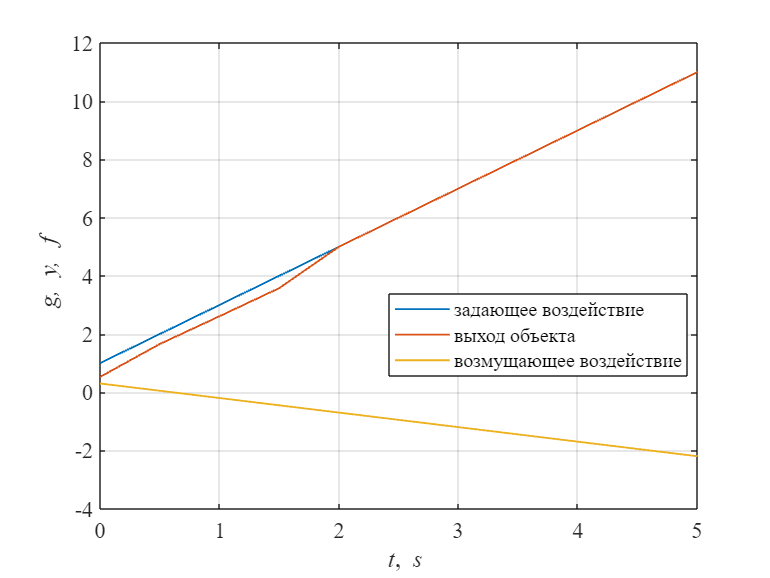

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,g,'LineWidth',1)
hold on
grid on
plot(t,y,'LineWidth',1)
plot(t,f,'LineWidth',1)
% ylim([0 4.1])
xlabel('\it t\rm,\it s')
ylabel('\it g, y, f')
legend('задающее воздействие','выход объекта','возмущающее воздействие','Location','best')

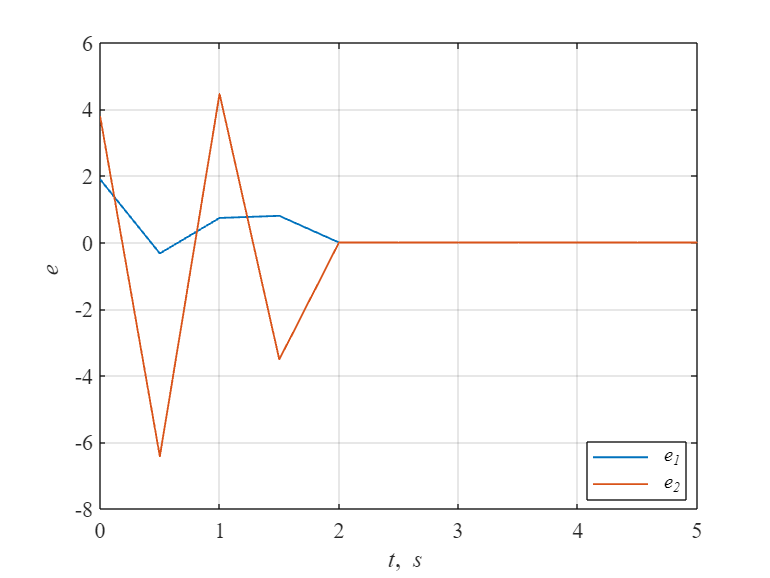

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,e(:,1),'LineWidth',1)
hold on
grid on
plot(t,e(:,2),'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it e')
legend('\it e_1','\it e_2','Location','best')

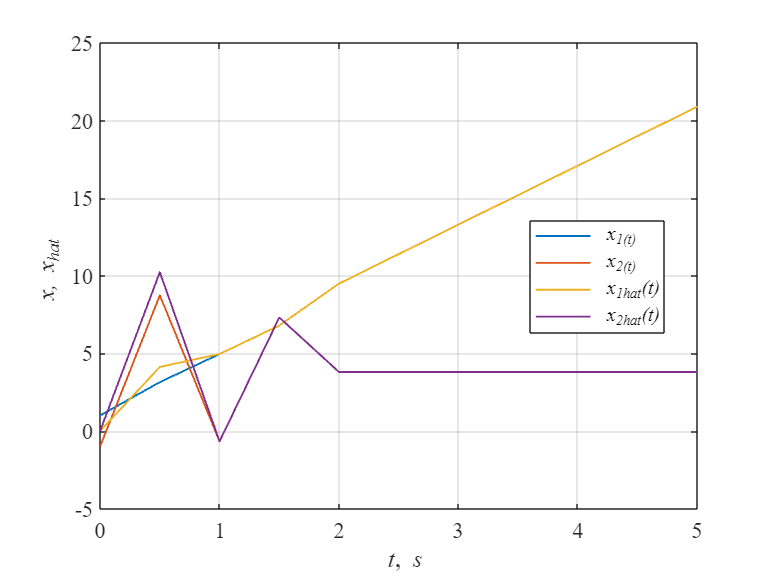

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,x(:,1),'LineWidth',1)
hold on
grid on
plot(t,x(:,2),'LineWidth',1)
plot(t,x_hat(:,1),'LineWidth',1)
plot(t,x_hat(:,2),'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it x, x_{hat}')
legend('\it x_1(t)','\it x_2(t)','\it x_1_{hat}(t)','\it x_2_{hat}(t)','Location','best')

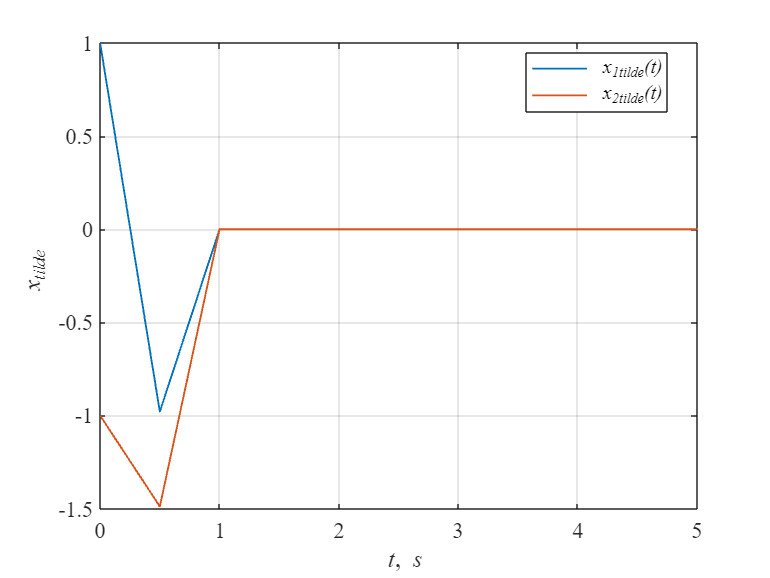

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,x_tilde(:,1),'LineWidth',1)
hold on
grid on
plot(t,x_tilde(:,2),'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it x_{tilde}')
legend('\it x_1_{tilde}(t)','\it x_2_{tilde}(t)','Location','best')